This is my Matlab file for the project in the course Transformmetoder

Constants:

r = 5000

r = 5000

c = 20*10^-9

c = 2.0000e-08

l = 50*10^-3

l = 0.0500


t = linspace(0,0.002,2000);

Circuit values

omega_0 = 1/sqrt(l*c)

omega_0 = 3.1623e+04

alpha = 1/(2*r*c)

alpha = 5000

omega_d = sqrt(omega_0^2 - alpha^2)

omega_d = 3.1225e+04

u_ut = 1 - (2*alpha/omega_d) .* exp(-alpha*t) .* sin(omega_d * t) ;

Transferfunction

s = tf("s");

H = (s^2 +omega_0^2)/(s^2 + omega_0^2 + 2*alpha * s)

H =        s^2 + 1e09
  --------------------
  s^2 + 10000 s + 1e09
 
Continuous-time transfer function.



[u_num, t_num] = step(H, t);

Plots

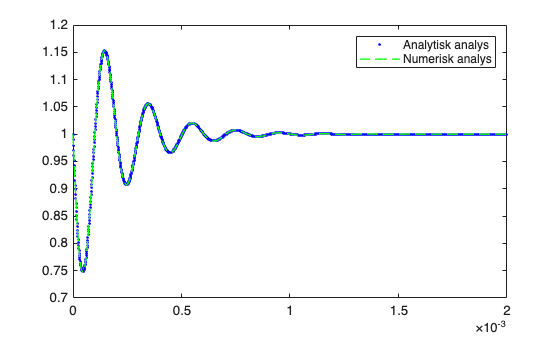

plot(t, u_ut, "b.", LineWidth=1)
hold on
plot(t_num, u_num, "g--", LineWidth = 1)
hold off 

legend("Analytisk analys", "Numerisk analys")

Bode diagram

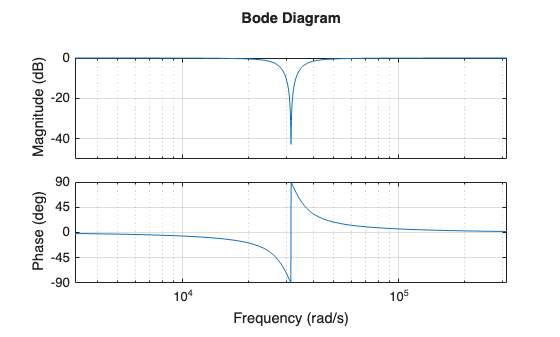

w = logspace(3.5, 5.5, 2000);
bode(H, w)
grid on;

By visual inspection I can see that it is an bandpass filter. The filters lets both low and high frequencies pass through but not frequencies around 3.16 * 10^4.

For the square wave input I use the fourier series from The BETA mathematics handbook for engineers. 


$$f(t) = \frac{2h}{\pi} \sum_{n=1}^{\infty} \frac{1 - \cos(n\pi\alpha)}{n} \sin\left(\frac{n\pi t}{L}\right)$$


alpha is 0.5

h is 0.5

and I add a DC with 0.5 voltage to get up the bottom voltage to zero.

for every even n we get zero because 1 - 1 = 0


$$x(t) = \frac{1}{2} + \frac{2}{\pi} \sum_{k=1,3,5,\dots}^{\infty} \frac{1}{k} \sin\left(\frac{k\pi t}{L}\right)$$


T0 = 0.2e-3;

x_str = strings(5, 1);
freq = zeros(5, 1);
gain = zeros(5, 1);
phase = zeros(5, 1);
y_str = strings(5, 1);

